# This file collects all the math for the Estimated Kalman Filter

## Plotting Functions

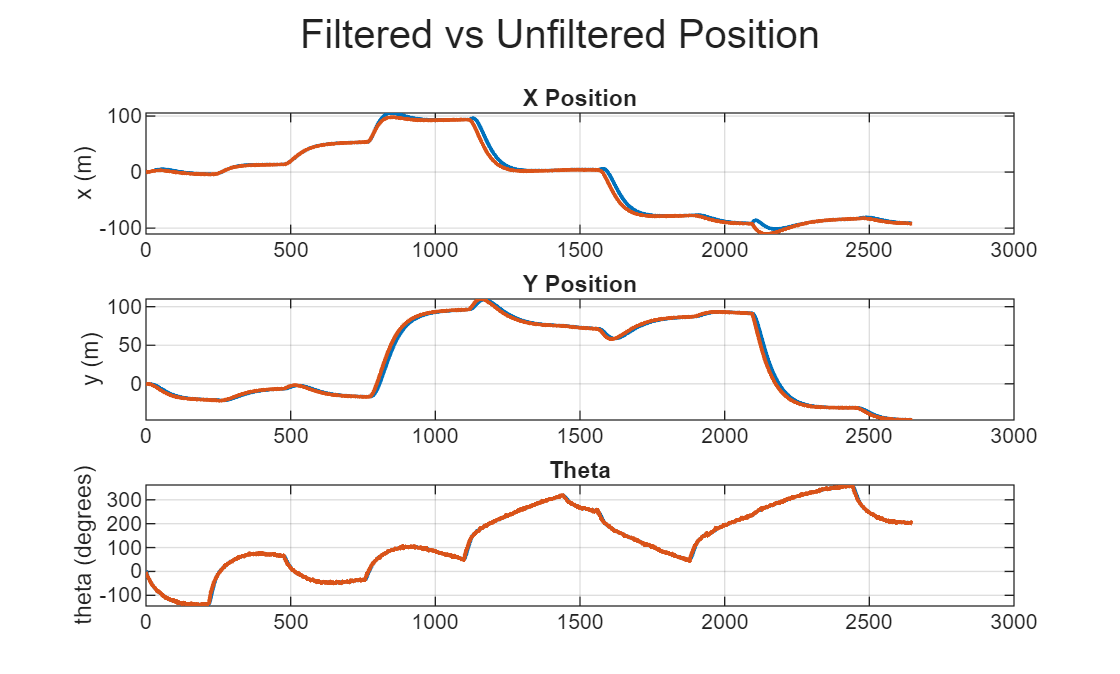

set(0, 'DefaultFigureWindowStyle', 'normal');
% Define colours used for plotting (hex codes)
c1 = '#0072BD'; c2 = '#D95319'; c3 = '#77AC30'; c4 = '#EDB120';
timestruct = linspace(0, length(filtered_ground_robot_state), length(filtered_ground_robot_state));

% Position
figure
subplot(3,1,1)
plot(timestruct, filtered_ground_robot_state(:,1), 'Color', c1, 'LineWidth', 1.5); hold on
plot(timestruct, ground_robot_state(:,1), 'Color', c2, 'LineWidth', 1.5)
title('X Position'); ylabel('x (m)'); grid on
% legend('X Position Filtered', 'X Position Unfiltered')

subplot(3,1,2)
plot(timestruct, filtered_ground_robot_state(:,2), 'Color', c1, 'LineWidth', 1.5); hold on
plot(timestruct, ground_robot_state(:,2), 'Color', c2, 'LineWidth', 1.5)
title('Y Position'); ylabel('y (m)'); grid on
% legend('X Position Filtered', 'X Position Unfiltered')

subplot(3,1,3)
plot(timestruct, rad2deg(filtered_ground_robot_state(:,3)), 'Color', c1, 'LineWidth', 1.5); hold on
plot(timestruct, rad2deg(ground_robot_state(:,3)), 'Color', c2, 'LineWidth', 1.5)
title('Theta'); ylabel('theta (degrees)'); grid on
% legend('X Position Filtered', 'X Position Unfiltered')

sgtitle('Filtered vs Unfiltered Position')

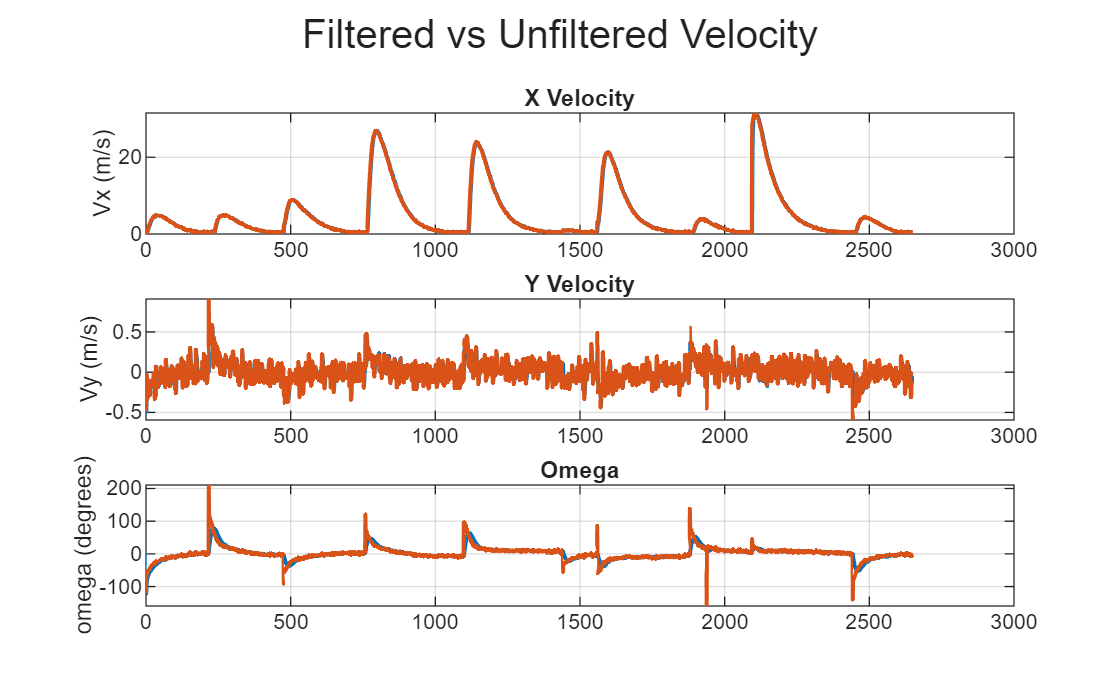


% Velocity
figure
subplot(3,1,1)
plot(timestruct, filtered_ground_robot_state(:,4), 'Color', c1, 'LineWidth', 1.5); hold on
plot(timestruct, ground_robot_state(:,4), 'Color', c2, 'LineWidth', 1.5)
title('X Velocity'); ylabel('Vx (m/s)'); grid on
% legend('X Position Filtered', 'X Position Unfiltered')

subplot(3,1,2)
plot(timestruct, filtered_ground_robot_state(:,5), 'Color', c1, 'LineWidth', 1.5); hold on
plot(timestruct, ground_robot_state(:,5), 'Color', c2, 'LineWidth', 1.5)
title('Y Velocity'); ylabel('Vy (m/s)'); grid on
% legend('X Position Filtered', 'X Position Unfiltered')

subplot(3,1,3)
plot(timestruct, rad2deg(filtered_ground_robot_state(:,6)), 'Color', c1, 'LineWidth', 1.5); hold on
plot(timestruct, rad2deg(ground_robot_state(:,6)), 'Color', c2, 'LineWidth', 1.5)
title('Omega'); ylabel('omega (degrees)'); grid on
% legend('X Position Filtered', 'X Position Unfiltered')

sgtitle('Filtered vs Unfiltered Velocity')